clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[3.42;0.473;4.01];
u31=[-0.856;-0.117;0.504];
r2=[-3.42;-0.473;-4.21];
u32=[0.856;0.117;0.504];
r3=[-10.14;-8.36;3.94];
u33=[-0.856;-0.117;-0.504];
r4=[-10.14;-8.36;-12.50];
u34=[-0.856;-0.117;-0.504];
r5=[7.69;-9.29;-4.28];
u35=[0.856;0.117;-0.504];
r6=[7.69;-9.29;12.16];
u36=[0.856;0.117;-0.504];
r7=[3.42;16.913;4.01];
u37=[-0.856;-0.117;0.504];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
% center and direction of spheroids

hold on
axis([0 10 0 10]);
for R3=1:1:10 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =    10.4500    1.0000    1.0019


ans =     9.2500    2.0000    1.0005


ans =     7.9500    3.0000    1.0069


ans =     6.7000    4.0000    1.0084


ans =     5.6500    5.0000    1.0083


ans =     4.8500    6.0000    1.0038


ans =     4.1500    7.0000    1.0008


ans =     3.4000    8.0000    1.0108


ans =     2.7000    9.0000    1.0005


ans =     1.8500   10.0000    1.0085



values1 = spcrv([[x1(1) x1 x1(end)];[y1(1) y1 y1(end)]],3);
plot(values1(1,:),values1(2,:),'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[238, 148, 138]/256, ...
    'DisplayName','1-2');

for R3=4:1:10 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans =    10.7000    4.0000    1.0006


ans =     7.8500    5.0000    1.0056


ans =     7.0500    6.0000    1.0025


ans =     6.6500    7.0000    1.0058


ans =     6.4500    8.0000    1.0012


ans =     6.3000    9.0000    1.0043


ans =     6.2000   10.0000    1.0062


 
values2 = spcrv([[x2(1) x2 x2(end)];[y2(1) y2 y2(end)]],3);
plot(values2(1,:),values2(2,:),'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[142, 152, 161]/256, ...
    'DisplayName','1-5');


for R3=1:1:10 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans =    11.3000    1.0000    1.0013


ans =     7.2500    2.0000    1.0032


ans =     6.9000    3.0000    1.0024


ans =     6.7500    4.0000    1.0133


ans =     6.7000    5.0000    1.0136


ans =     6.7000    6.0000    1.0058


ans =     6.7000    7.0000    1.0011


ans =     6.6500    8.0000    1.0130


ans =     6.6500    9.0000    1.0109


ans =     6.6500   10.0000    1.0094



values3 = spcrv([[x3(1) x3 x3(end)];[y3(1) y3 y3(end)]],3);
plot(values3(1,:),values3(2,:),'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[159, 190, 208]/256, ...
    'DisplayName','1-6');

for R3=1.4:0.8:11 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans =    18.1100    1.4000    1.0001


ans =     7.9600    2.2000    1.0010


ans =     7.1500    3.0000    1.0009


ans =     6.8600    3.8000    1.0024


ans =     6.7300    4.6000    1.0007


ans =     6.6500    5.4000    1.0017


ans =     6.6000    6.2000    1.0024


ans =     6.5700    7.0000    1.0020


ans =     6.5500    7.8000    1.0014


ans =     6.5300    8.6000    1.0025


ans =     6.5200    9.4000    1.0019



values4 = spcrv([[x4(1) x4 x4(end)];[y4(1) y4 y4(end)]],3);
plot(values4(1,:),values4(2,:),'color',[191, 144, 0]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[223, 199, 127]/256, ...
    'DisplayName','2-3');

for R1=4.4:0.2:10.4 %离心率
    R3=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r4,R1,R3,u32,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans =     4.4000   10.9100    1.0004


ans =     4.5000   10.2500    1.0002


ans =     4.6000    9.7200    1.0006


ans =     4.7000    9.3000    1.0004


ans =     4.8000    8.9500    1.0003


ans =     4.9000    8.6500    1.0007


ans =     5.0000    8.4000    1.0004


ans =     5.1000    8.1800    1.0005


ans =     5.2000    7.9900    1.0003


ans =     5.3000    7.8200    1.0004


ans =     5.4000    7.6700    1.0004


ans =     5.5000    7.5300    1.0012


ans = 1×3
    5.6000    7.4100    1.0011


ans = 1×3
    5.7000    7.3000    1.0012


ans = 1×3
    5.8000    7.2000    1.0013


ans = 1×3
    5.9000    7.1100    1.0012


ans = 1×3
    6.0000    7.0300    1.0007


ans = 1×3
    6.1000    6.9500    1.0013


ans = 1×3
    6.2000    6.8800    1.0013


ans = 1×3
    6.3000    6.8200    1.0003


ans = 1×3
    6.4000    6.7600    1.0002


ans = 1×3
    6.5000    6.7000    1.0009


ans = 1×3
    6.6000    6.6500    1.0005


ans = 1×3
    6.7000    6.6000    1.0007


ans = 1×3
    6.8000    6.5500    1.0016


ans = 1×3
    6.9000    6.5100    1.0010


ans = 1×3
    7.0000    6.4700    1.0009


ans = 1×3
    7.1000    6.4300    1.0014


ans = 1×3
    7.2000    6.4000    1.0001


ans = 1×3
    7.3000    6.3600    1.0015


ans = 1×3
    7.4000    6.3300    1.0011


ans = 1×3
    7.5000    6.3000    1.0011


ans = 1×3
    7.6000    6.2700    1.0014


ans = 1×3
    7.7000    6.2400    1.0021


ans = 1×3
    7.8000    6.2200    1.0007


ans = 1×3
    7.9000    6.1900    1.0021


ans = 1×3
    8.0000    6.1700    1.0013


ans = 1×3
    8.1000    6.1500    1.0008


ans = 1×3
    8.2000    6.1300    1.0005


ans = 1×3
    8.3000    6.1100    1.0004


ans = 1×3
    8.4000    6.0900    1.0006


ans = 1×3
    8.5000    6.0700    1.0010


ans = 1×3
    8.6000    6.0500    1.0017


ans = 1×3
    8.7000    6.0300    1.0025


ans = 1×3
    8.8000    6.0200    1.0009


ans = 1×3
    8.9000    6.0000    1.0021


ans = 1×3
    9.0000    5.9900    1.0008


ans = 1×3
    9.1000    5.9700    1.0024


ans = 1×3
    9.2000    5.9600    1.0014


ans = 1×3
    9.3000    5.9500    1.0005


ans = 1×3
    9.4000    5.9300    1.0025


ans = 1×3
    9.5000    5.9200    1.0019


ans = 1×3
    9.6000    5.9100    1.0014


ans = 1×3
    9.7000    5.9000    1.0011


ans = 1×3
    9.8000    5.8900    1.0008


ans = 1×3
    9.9000    5.8800    1.0007


ans = 1×3
   10.0000    5.8700    1.0006


ans = 1×3
   10.1000    5.8600    1.0007


ans = 1×3
   10.2000    5.8500    1.0008


ans = 1×3
   10.3000    5.8400    1.0011


ans = 1×3
   10.4000    5.8300    1.0014


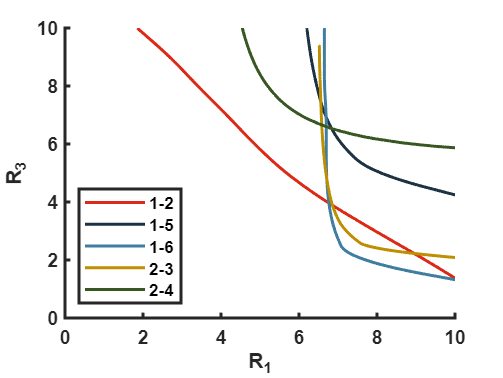


values5 = spcrv([[x5(1) x5 x5(end)];[y5(1) y5 y5(end)]],3);
plot(values5(1,:),values5(2,:),'color',[56, 87, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','2-4');

set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','southwest');
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end
